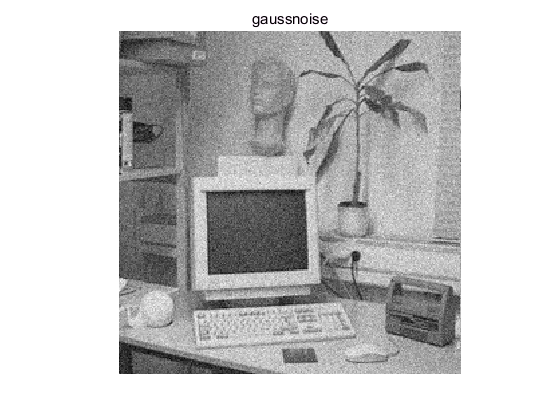

clear

office=office256;

add=gaussnoise(office,16);
sap=sapnoise(office,0.1,255);

%%%gaussnoise
figure
showgrey(add);
title('gaussnoise');

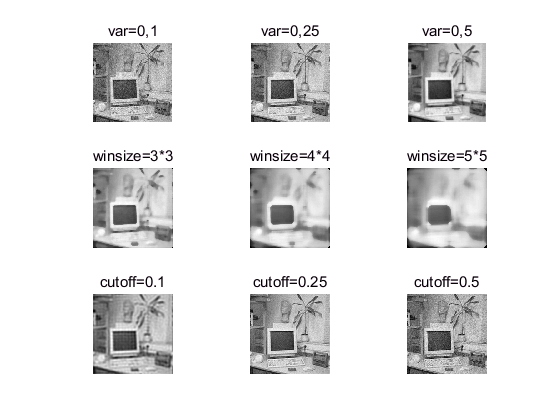


%%%%gaussfilter
figure
subplot(3,3,1)
showgrey(gaussfft(add,0.5));
title('var=0,5');
subplot(3,3,2)
showgrey(gaussfft(add,1.0));
title('var=1.0');
subplot(3,3,3)
showgrey(gaussfft(add,10.0));
title('var=10.0');


%%%medfilter
%figure
subplot(3,3,4)
showgrey(medfilt(add,2*2));
title('winsize=2*2');
subplot(3,3,5)
showgrey(medfilt(add,3*3));
title('winsize=3*3');
subplot(3,3,6)
showgrey(medfilt(add,4*4));
title('winsize=4*4');


%%%ideal low pass filter
%figure
subplot(3,3,7)
showgrey(ideal(add,0.1));
title('cutoff=0.1');
subplot(3,3,8)
showgrey(ideal(add,0.25));
title('cutoff=0.25');
subplot(3,3,9)
showgrey(ideal(add,0.5));
title('cutoff=0.5');

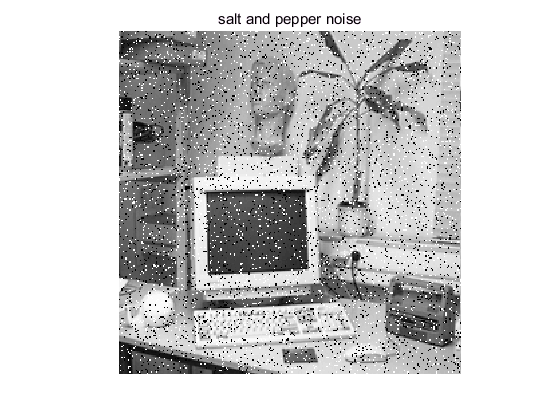


%%%salt and pepper noise
figure
showgrey(sap);
title('salt and pepper noise');

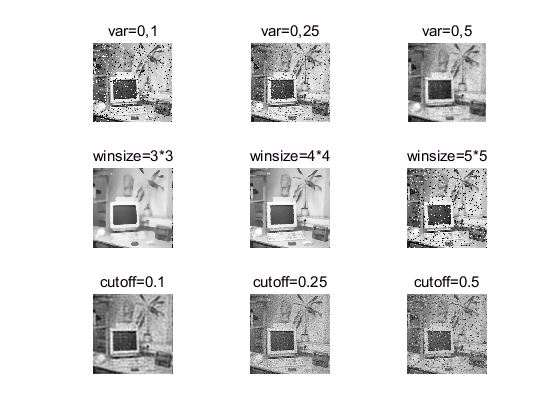


%%%%gaussfilter
figure
subplot(3,3,1)
showgrey(gaussfft(sap,0.5));
title('var=0.5');
subplot(3,3,2)
showgrey(gaussfft(sap,1.0));
title('var=1.0');
subplot(3,3,3)
showgrey(gaussfft(sap,10.0));
title('var=10.0');


%%%medfilter
%figure
subplot(3,3,4)
showgrey(medfilt(sap,2*2));
title('winsize=2*2');
subplot(3,3,5)
showgrey(medfilt(sap,3*3));
title('winsize=3*3');
subplot(3,3,6)
showgrey(medfilt(sap,4*4));
title('winsize=4*4');


%%%ideal low pass filter
%figure
subplot(3,3,7)
showgrey(ideal(sap,0.1));
title('cutoff=0.1');
subplot(3,3,8)
showgrey(ideal(sap,0.25));
title('cutoff=0.25');
subplot(3,3,9)
showgrey(ideal(sap,0.5));
title('cutoff=0.5');